# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------ 
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} U =  \sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		G_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$, $G_t$ is age-specific average of income and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
	       G_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$



$$y_t = \begin{cases}
		G_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current  working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model 



## Calculate $G_t$ and merge to the model

%% Load the dataset
filename = 'C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model\data_processed.csv';
data = readtable(filename);

% Display column names
disp('Column names in the dataset:');

Column names in the dataset:


disp(data.Properties.VariableNames);

  Columns 1 through 10

    {'tinh'}    {'huyen'}    {'xa'}    {'diaban'}    {'hoso'}    {'matv'}    {'hsize'}    {'m1ac2'}    {'m1ac3'}    {'age'}

  Columns 11 through 14

    {'HH_income'}    {'HH_consumption'}    {'HH_consumption_…'}    {'HH_Wealth'}



%% Ensure no zero or negative incomes before taking the log
data.HH_income(data.HH_income <= 0) = NaN;
data.log_income = log(data.HH_income);

%% Compute average log income per age group
age_groups = unique(data.age);
Gt = zeros(length(age_groups), 1);

for i = 1:length(age_groups)
    age = age_groups(i);
    avg_log_income = mean(data.log_income(data.age == age), 'omitnan');
    Gt(i) = exp(avg_log_income);
end

% Display results
table_results = table(age_groups, Gt, 'VariableNames', {'Age', 'G_t'});

% Save G_t values to CSV
writetable(table_results, fullfile(main, 'Gt_values.csv'));
disp(table_results);

    Age     G_t  
    ___    ______

    25       9589
    26     9827.8
    27      10760
    28       9407
    29      12887
    30      11887
    31      11361
    32      10398
    33      11509
    34      13250
    35      11515
    36      12275
    37     9700.7
    38      10668
    39      13044
    40      11872
    41      13211
    42      15305
    43      14074
    44      13224
    45      14376
    46      15435
    47      16075
    48      15323
    49      18932
    50      16383
    51      17174
    52      15797
    53      15357
    54      16981
    55      20478
    56      14837
    57      17276
    58      15273
    59      14793
    60      17721
    61      15657
    62      12207
    63      15767
    64      13210
    65      12239
    66      18434
    67      16649
    68      11911
    69      13787
    70      16013
    71     8643.1
    72      15008
    73      10866
    74     87

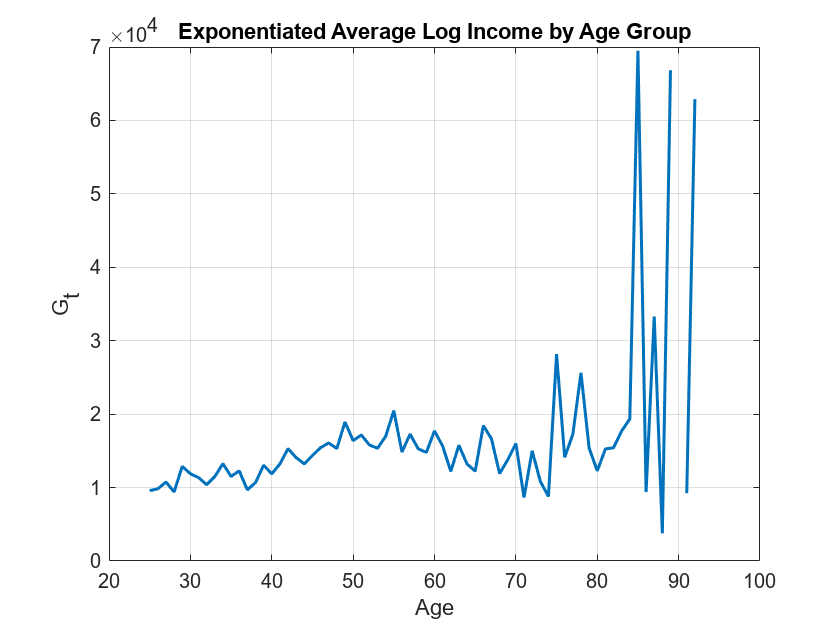

%% Plot Gt against age
figure;
plot(age_groups, Gt, '-', 'LineWidth', 1.5);
xlabel('Age');
ylabel('G_t');
title('Exponentiated Average Log Income by Age Group');
grid on;
saveas(gcf, fullfile(figout, 'gt.png'));

## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 3.2656 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

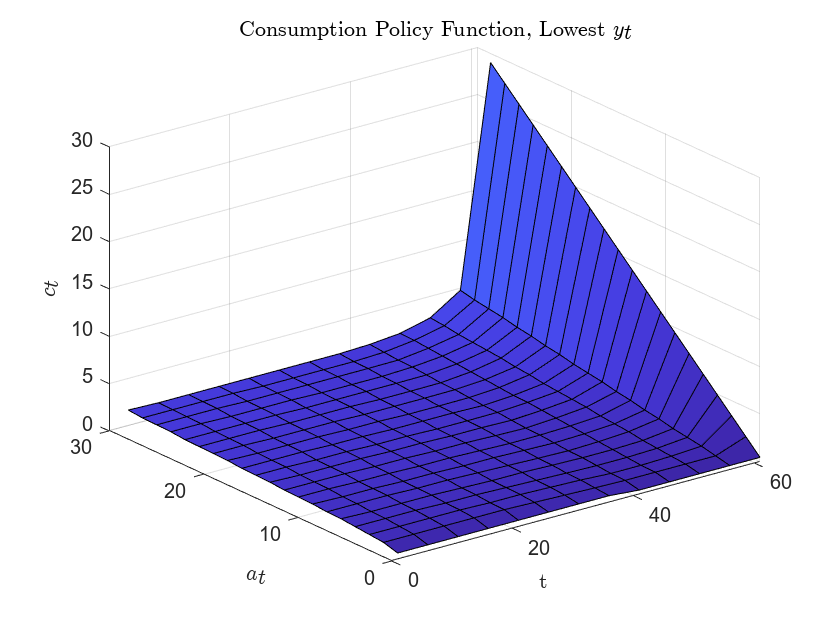

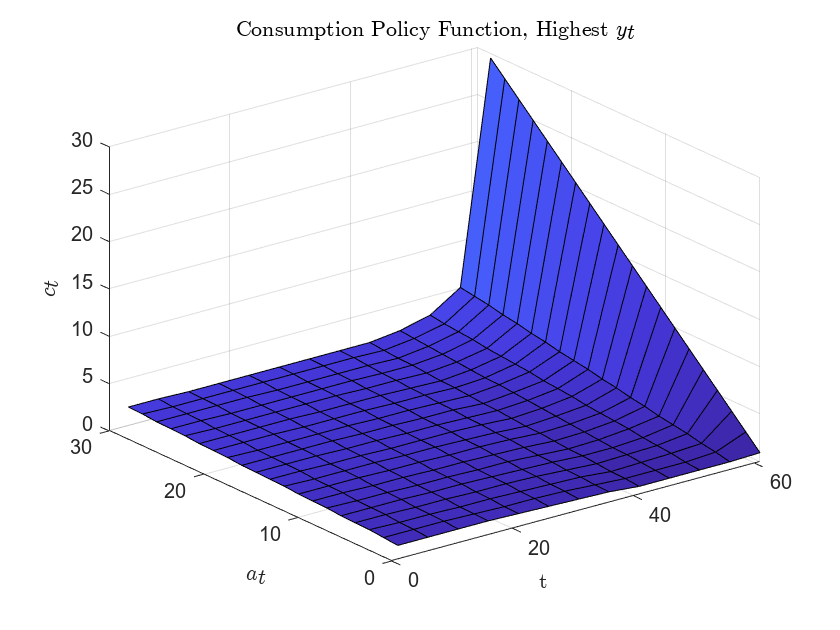

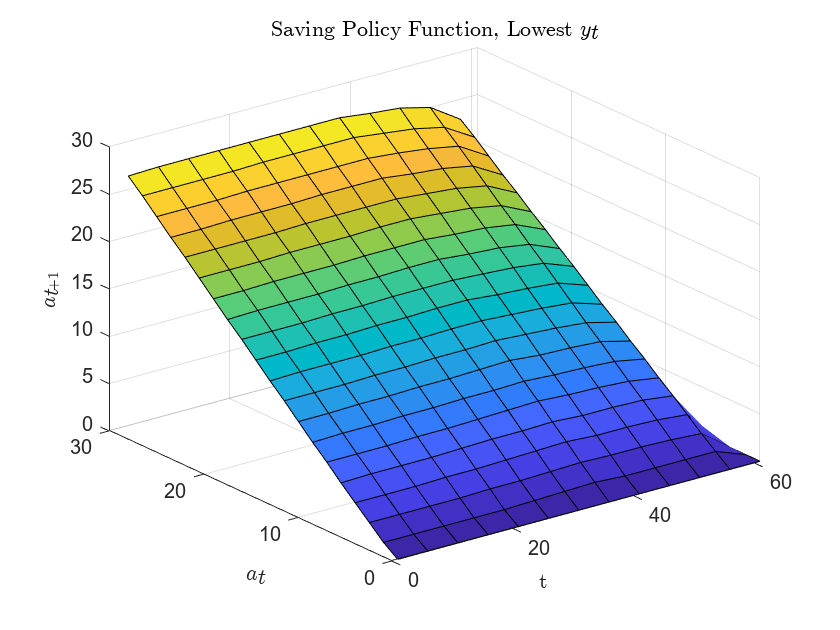

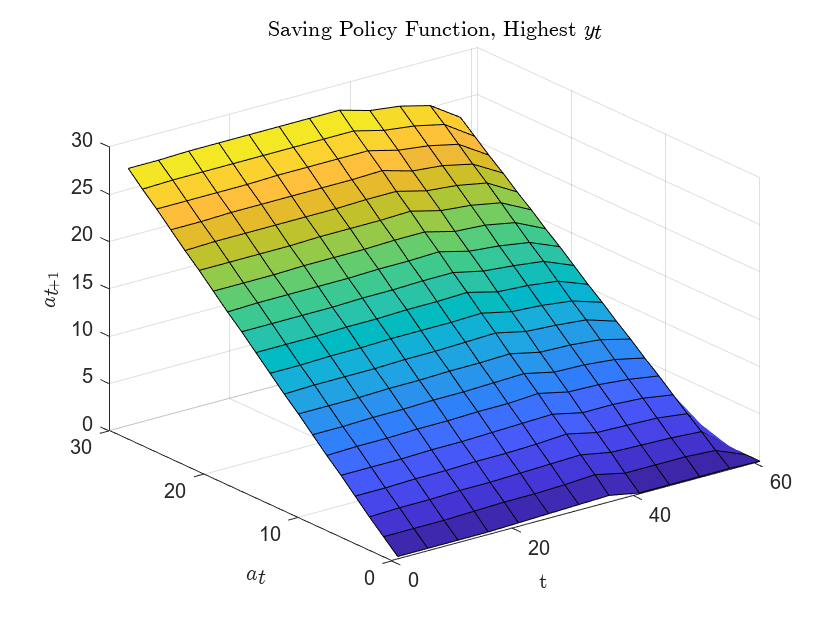

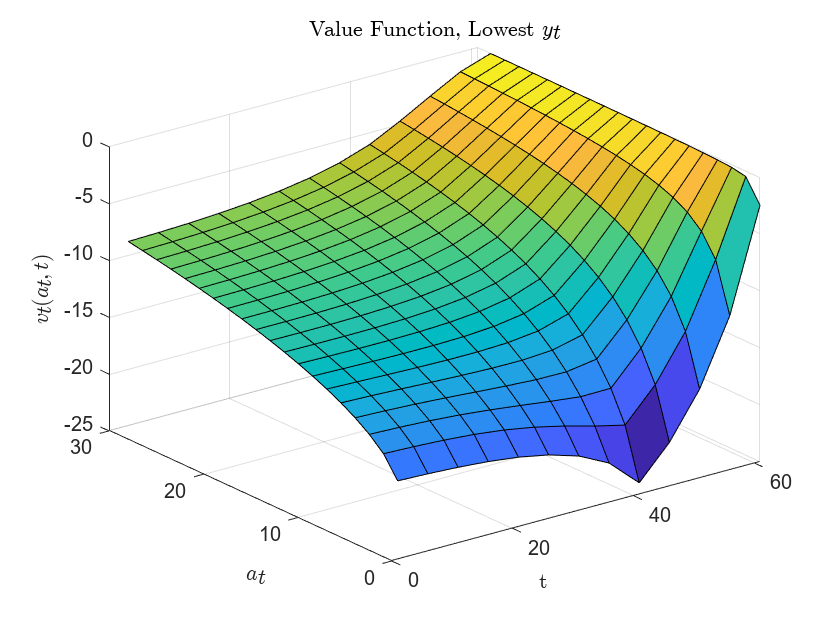

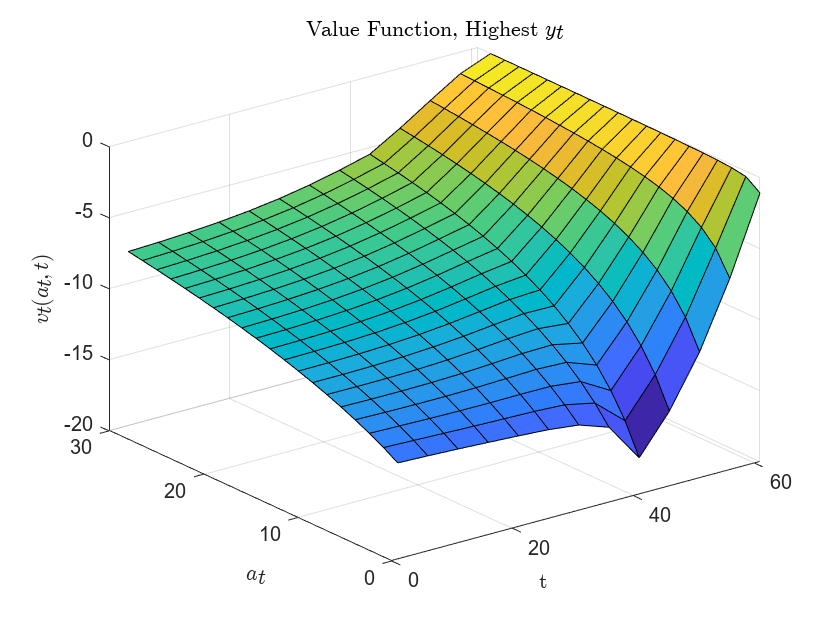

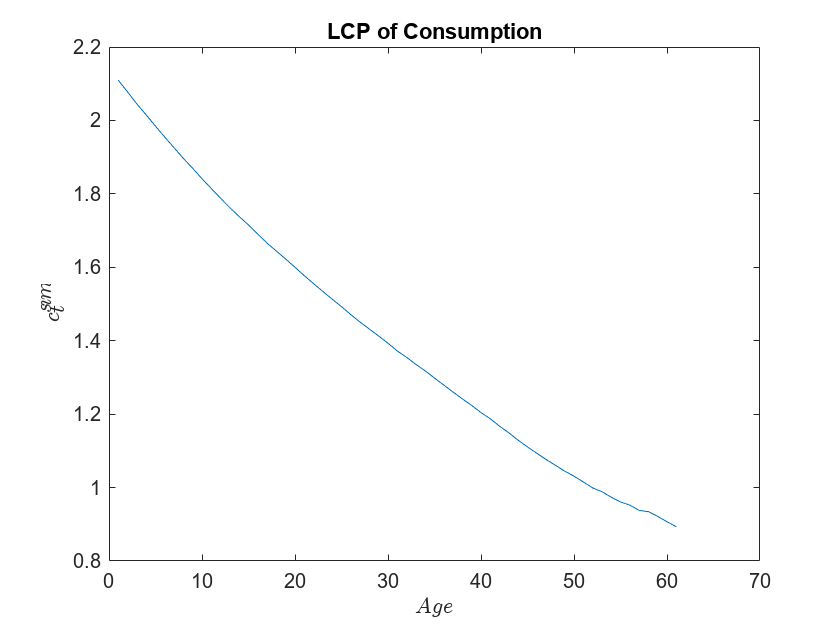

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

## Simulate the model for different values of  $\beta$ and  $\gamma$

%% Run Scenarios
% Define parameter values
betas = [0.90, 0.92, 0.94, 0.96];
gammas = [2.00, 3.00, 4.00, 5.00];

% Plot life cycle profiles for different beta values
figure;
hold on;
colors = lines(length(betas));

for i = 1:length(betas)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = betas(i);
    par.gamma = 2.00;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Initialize storage for life cycle profiles
    lcp_c1 = nan(par.T,1);
    lcp_a1 = nan(par.T,1);
    lcp_u1 = nan(par.T,1);

    for t = 1:par.T
        % Compute averages across all individuals
        lcp_c1(t) = mean(sim.csim(sim.tsim ==t), 'omitnan');
        lcp_a1(t) = mean(sim.asim(sim.tsim ==t), 'omitnan');
        lcp_u1(t) = mean(sim.usim(sim.tsim ==t), 'omitnan');
    end

    % Plot consumption profile
    plot(1:par.T, lcp_c1, 'Color', colors(i,:), 'DisplayName', sprintf('\beta = %.2f', betas(i)));
    plot(1:par.T, lcp_a1, 'Color', colors(i,:), 'DisplayName', sprintf('\beta = %.2f', betas(i)));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


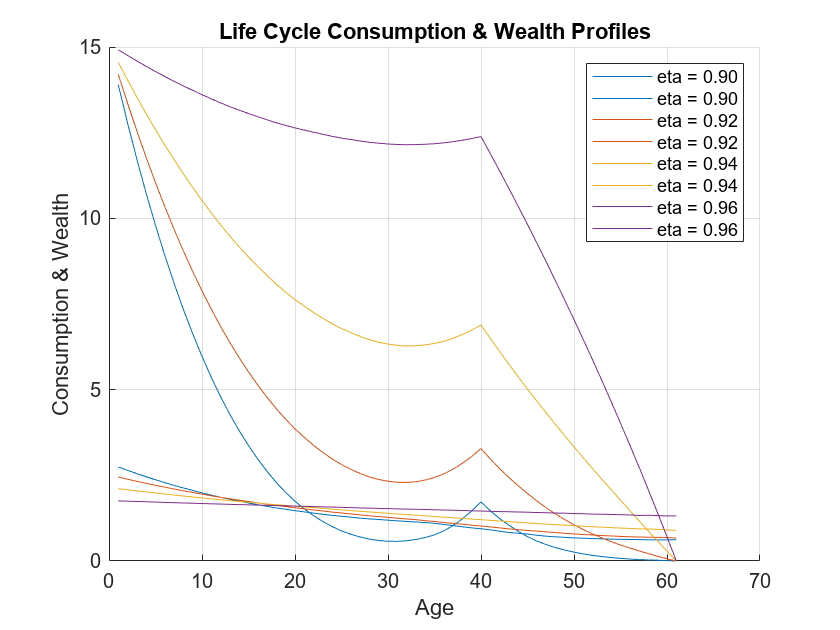

xlabel('Age');
ylabel('Consumption & Wealth');
title('Life Cycle Consumption & Wealth Profiles');
legend('show');
grid on;
hold off;

%% Plot life cycle profiles for different gamma values
figure;
hold on;
colors = lines(length(gammas));

for j = 1:length(gammas)
    par = model.setup;
    par = model.gen_grids(par); 
    par.gamma = gammas(j);
    par.beta = 0.96;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Initialize storage for life cycle profiles
    lcp_c2 = nan(par.T,1);
    lcp_a2 = nan(par.T,1);
    lcp_u2 = nan(par.T,1);

    for t = 1:par.T
        % Compute averages across all individuals at age t
        indices = (sim.tsim == t);
        lcp_c2(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a2(t) = mean(sim.asim(indices), 'omitnan');
        lcp_u2(t) = mean(sim.usim(indices), 'omitnan');
    end

    % Plot consumption and savings profiles
    plot(1:par.T, lcp_c2, 'Color', colors(j,:), 'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f (Consumption)', gammas(j)));
    plot(1:par.T, lcp_a2, 'Color', colors(j,:), 'LineStyle', '--', 'DisplayName', sprintf('\\gamma = %.2f (Assets)', gammas(j)));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


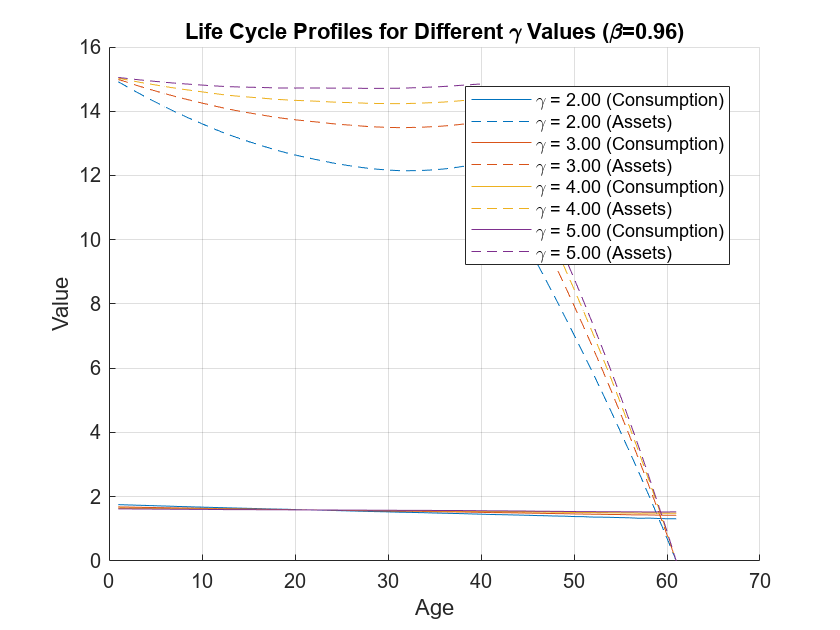

hold off;
xlabel('Age');
ylabel('Value');
title('Life Cycle Profiles for Different \gamma Values (\beta=0.96)');
legend('show', 'Location', 'best');
grid on;

%% Compute and plot heatmap of average simulated wealth
avg_wealth = nan(length(betas), length(gammas)); % Ensure NaN initialization

for i = 1:length(betas)
    for j = 1:length(gammas)
        % Initialize and update parameters
        par = model.setup;
        par = model.gen_grids(par);
        par.beta = betas(i);
        par.gamma = gammas(j);

        % Solve model for given parameters
        sol = solve.lc(par);
        sim = simulate.lc(par, sol);

        % Compute average wealth
        avg_wealth(i,j) = mean(sim.asim(:), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

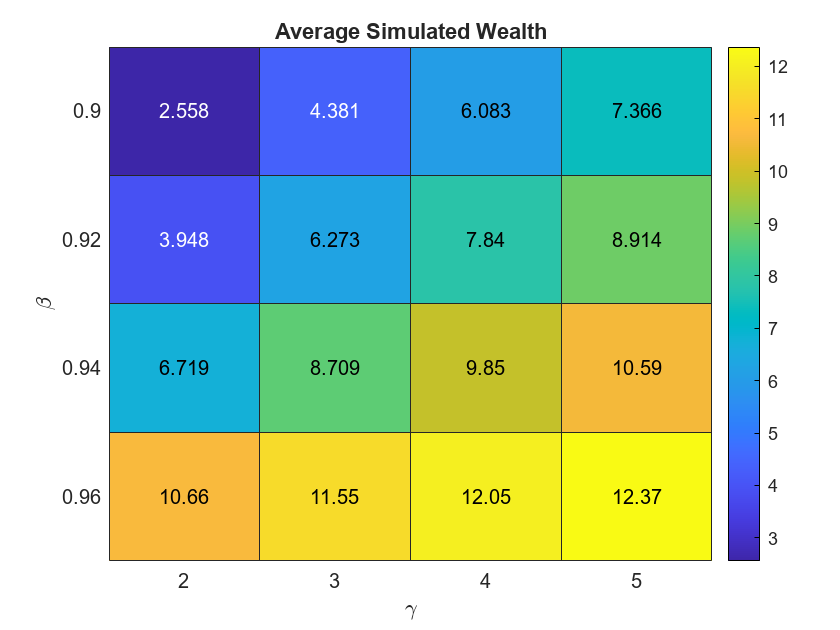

Error using matlab.graphics.chart.HeatmapChart/set
Unrecognized property YDir for class HeatmapChart.

% Create heatmap
figure;
h = heatmap(string(gammas), string(betas), avg_wealth, 'Colormap', parula);
xlabel('\gamma');
ylabel('\beta');
title('Average Simulated Wealth');